Brakes = readfis("Brake_System5.fis");
CruiseControl = readfis("CruiseControl.fis");

Now plot the FISs

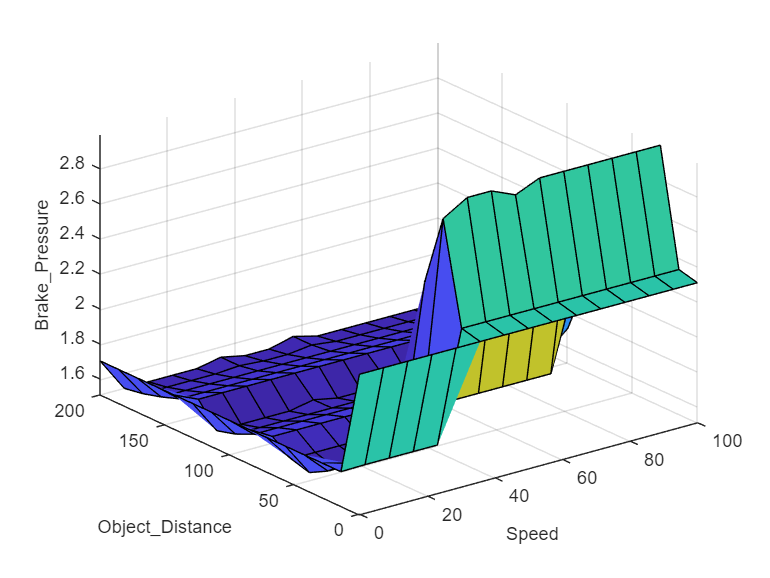

gensurf(Brakes);

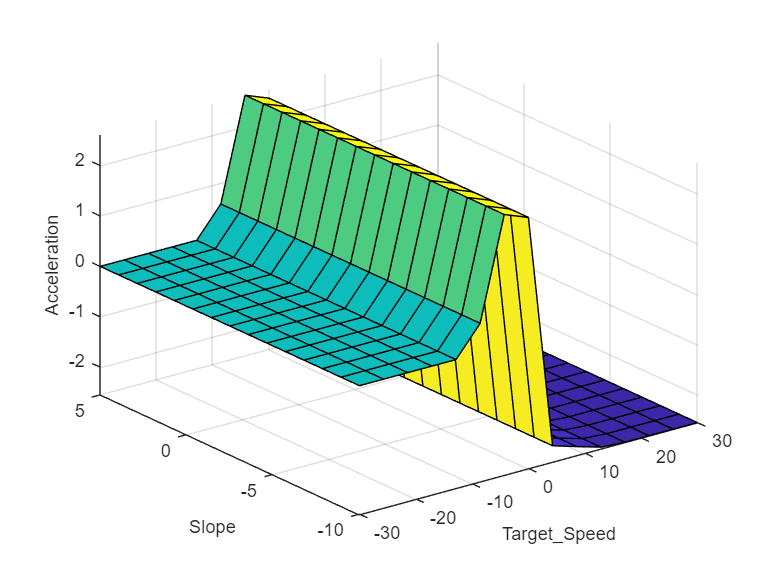

Matlab produced an error, seems to be an internal bug

try
    test = gensurf(CruiseControl); % why is matlab so shit?
catch
    fprintf("Matlab produced an error, seems to be an internal bug")
end

Now lets combine them into a tree

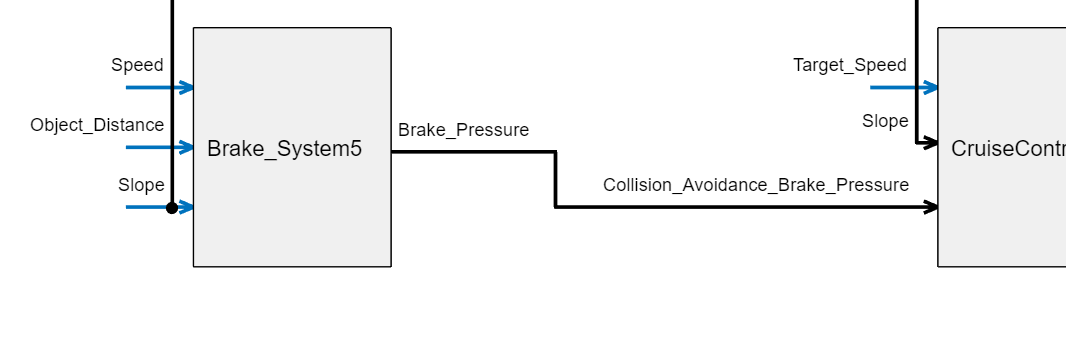

incConnection = ["Brake_System5/Brake_Pressure" "CruiseControl/Collision_Avoidance_Brake_Pressure"];
slopeConnection = ["Brake_System5/Slope" "CruiseControl/Slope"];

fuzzTree = fistree([Brakes CruiseControl], [incConnection;slopeConnection]);
plotfis(fuzzTree)

And now lets plot it

samples_per_dimension = 50;

speed = linspace(0, 100, samples_per_dimension);
distance = linspace(0, 200, samples_per_dimension);
slope = linspace(-10, 5, samples_per_dimension);
target = linspace(-30, 30, samples_per_dimension);

z = ones(length(speed), length(distance), length(slope));
brake_pressure = zeros(size(z));

a = speed;
b = repmat(repelem(distance, samples_per_dimension), samples_per_dimension, 1);
c = repmat(distance, samples_per_dimension);


warning("off");
for speedind = 1:length(speed)
    for distanceind = 1:length(distance)
        for slopeind = 1:length(slope)
            %for targetind = 1:length(target)
                brake_pressure(speedind, distanceind, slopeind) = evalfis(Brakes, [speed(speedind) distance(distanceind) slope(slopeind)]);
                z(speedind, distanceind, slopeind) = evalfis(fuzzTree, [speed(speedind) slope(slopeind) brake_pressure(speedind, distanceind, slopeind) 0]);
            %end
        end
    end
end
warning("on");

speed = repmat(transpose(a), 1, samples_per_dimension * samples_per_dimension);
speed = reshape(speed, 1, []);
distance = reshape(b, 1, []);
slope = reshape(c, 1, []);
acceleration = abs(reshape(z, 1, []));
brake_pressure = reshape(brake_pressure, 1, []);

Plot the data

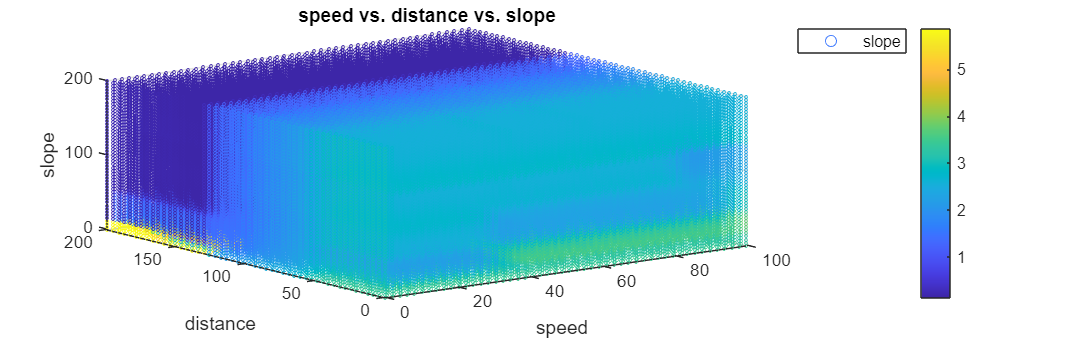

% Create scatter3 of speed, distance, and slope
s2 = scatter3(speed,distance,slope,acceleration,brake_pressure,"DisplayName","slope");

% Add xlabel, ylabel, zlabel, title, and legend
xlabel("speed")
ylabel("distance")
zlabel("slope")
title("speed vs. distance vs. slope")
legend
colorbar()